# Question 4

clear
clc
close all

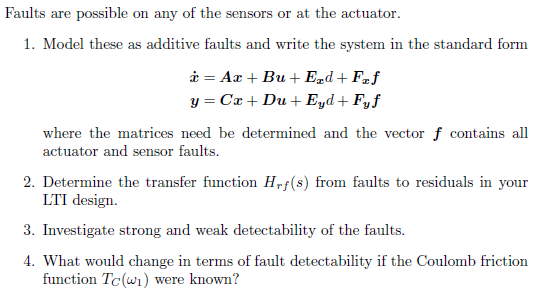

## Question 1

% Define states as symbols
syms J_1 J_2 J_3 k_1 k_2 b_1 b_2 b_3 
syms theta_1 theta_2 theta_3 omega_1 omega_2 omega_3 u_1 u_2 d 
syms f_u1 f_u2 f_y1 f_y2 f_y3


% Write system equations
eq1 = omega_1;
eq2 = 1/J_1 * (u_1 + f_u1 - b_1*omega_1 - k_1 * (theta_1 - theta_2) - d);
eq3 = omega_2;
eq4 = 1/J_2 * (u_2 + f_u2 - b_2 * omega_2 - k_1*(theta_2 - theta_1) - k_2*(theta_2-theta_3));
eq5 = omega_3;
eq6 = 1/J_3 * (-b_3 * omega_3 - k_2*(theta_3 - theta_2));

y_1 = theta_1 + f_y1;
y_2 = theta_2 + f_y2;
y_3 = theta_3 + f_y3;



A = ((jacobian([eq1, eq2, eq3, eq4, eq5, eq6],[theta_1, omega_1, theta_2, omega_2, theta_3, omega_3])))

$$A = \left(\begin{array}{cccccc} 0 & 1 & 0 & 0 & 0 & 0\\ -\frac{k_{1}}{J_{1}} & -\frac{b_{1}}{J_{1}} & \frac{k_{1}}{J_{1}} & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ \frac{k_{1}}{J_{2}} & 0 & -\frac{k_{1}+k_{2}}{J_{2}} & -\frac{b_{2}}{J_{2}} & \frac{k_{2}}{J_{2}} & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & \frac{k_{2}}{J_{3}} & 0 & -\frac{k_{2}}{J_{3}} & -\frac{b_{3}}{J_{3}} \end{array}\right)$$

B = ((jacobian([eq1, eq2, eq3, eq4, eq5, eq6],[u_1, u_2])))

$$B = \left(\begin{array}{cc} 0 & 0\\ \frac{1}{J_{1}} & 0\\ 0 & 0\\ 0 & \frac{1}{J_{2}}\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

C = ((jacobian([y_1; y_2; y_3],[theta_1, omega_1, theta_2, omega_2, theta_3, omega_3])))

$$C = \left(\begin{array}{cccccc} 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 \end{array}\right)$$

D = ((jacobian([y_1; y_2; y_3], [u_1, u_2])))

$$D = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$


Ex = ((jacobian([eq1, eq2, eq3, eq4, eq5, eq6], d)))

$$Ex = \left(\begin{array}{c} 0\\ -\frac{1}{J_{1}}\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

Ey = ((jacobian([y_1; y_2; y_3], d)))

$$Ey = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$


Fx = (jacobian([eq1,eq2, eq3, eq4, eq5, eq6],[f_u1, f_u2, f_y1, f_y2, f_y3]))

$$Fx = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ \frac{1}{J_{1}} & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & \frac{1}{J_{2}} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

Fy = (jacobian([y_1; y_2; y_3],[f_u1, f_u2, f_y1, f_y2, f_y3]))

$$Fy = \left(\begin{array}{ccccc} 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

The fault vector

f = [f_u1, f_u2, f_y1, f_y2, f_y3].'

$$f = \left(\begin{array}{c} f_{\mathrm{u1}}\\ f_{\mathrm{u2}}\\ f_{\mathrm{y1}}\\ f_{\mathrm{y2}}\\ f_{\mathrm{y3}} \end{array}\right)$$

## Question 2

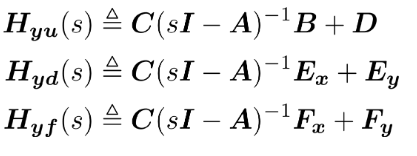

syms s omega_n zeta

Hyu = simplify(C/(s*eye(length(A)) - A)*B + D);
Hyd = simplify(C/(s*eye(length(A)) - A)*Ex + Ey);
Hyf = simplify(C/(s*eye(length(A)) - A)*Fx + Fy);


H = [Hyu Hyd; eye(2) zeros(2,1)];       % Construct H(s)
F = simplify(null(H')');    % Obtain the left nullspace basis

Q = [1, 0; 0, omega_n^2/(s^2 + 2 * zeta * omega_n * s + omega_n^2)]; % Define the filter

F = Q*F

$$F = \begin{array}{l} \left(\begin{array}{ccccc} 0 & -\frac{k_{2}}{\sigma_{2}} & 1 & 0 & 0\\ \frac{k_{1}\,{\omega_{n}}^{2}}{\sigma_{1}} & -\frac{{\omega_{n}}^{2}\,\left(k_{1}\,k_{2}+b_{2}\,k_{2}\,s+b_{3}\,k_{1}\,s+b_{3}\,k_{2}\,s+J_{2}\,J_{3}\,s^{4}+J_{2}\,b_{3}\,s^{3}+J_{3}\,b_{2}\,s^{3}+J_{2}\,k_{2}\,s^{2}+J_{3}\,k_{1}\,s^{2}+J_{3}\,k_{2}\,s^{2}+b_{2}\,b_{3}\,s^{2}\right)}{\sigma_{2}\,\sigma_{1}} & 0 & 0 & \frac{{\omega_{n}}^{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\omega_{n}}^{2}+2\,\zeta \,\omega_{n}\,s+s^{2}\\ \sigma_{2}=J_{3}\,s^{2}+b_{3}\,s+k_{2} \end{array}$$


% Determine residual generator
Vry = F(:,1:size(C,1));
Vru = F(:,size(C,1)+1 : end);

Hrf = simplify(Vry * Hyf)

$$Hrf = \begin{array}{l} \left(\begin{array}{ccccc} 0 & 0 & 0 & -\frac{k_{2}}{\sigma_{2}} & 1\\ 0 & -\frac{{\omega_{n}}^{2}}{\sigma_{1}} & \frac{k_{1}\,{\omega_{n}}^{2}}{\sigma_{1}} & -\frac{{\omega_{n}}^{2}\,\left(k_{1}\,k_{2}+b_{2}\,k_{2}\,s+b_{3}\,k_{1}\,s+b_{3}\,k_{2}\,s+J_{2}\,J_{3}\,s^{4}+J_{2}\,b_{3}\,s^{3}+J_{3}\,b_{2}\,s^{3}+J_{2}\,k_{2}\,s^{2}+J_{3}\,k_{1}\,s^{2}+J_{3}\,k_{2}\,s^{2}+b_{2}\,b_{3}\,s^{2}\right)}{\sigma_{2}\,\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\omega_{n}}^{2}+2\,\zeta \,\omega_{n}\,s+s^{2}\\ \sigma_{2}=J_{3}\,s^{2}+b_{3}\,s+k_{2} \end{array}$$

## Numeric$0$

addpath('./Data')
addpath('./Models')

load('ECP_values.mat');
% Physical system parameters
J_1 = ECP_values(1);            % Disk 1 inertia kgm^2
J_2 = ECP_values(2);            % Disk 2 inertia kgm^2
J_3 = ECP_values(3);            % Disk 3 inertia kgm^2
k_1 = ECP_values(4);            % Shaft 1-2 stiffness Nm/rad
k_2 = ECP_values(5);            % Shaft 2-3 stiffness Nm/rad
b_1 = mean(ECP_values([6 7]));  % Disk 1 damping and friction Nms/rad
b_2 = mean(ECP_values([8 9]));  % Disk 2 damping and friction Nms/rad
b_3 = mean(ECP_values([10 11]));% Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                     % Threshold angular velocity rad/s

% The system states are [theta_1;omega_1;theta_2;omega_2;theta_3;omega_3]
x_0 = [0;0;0;0;0;0];            % Initial conditions
T_s = 0.004;                    % Sampling period
sigma_meas = 0.0093*eye(3);     % Measurements covariance matrix

% Load data
load ECP502Data.mat


omega_n = 1;
zeta = 0.7;

Hrf = [0, 0, 0, -k_2/(J_3*s^2 + b_3*s + k_2), 1; 
    0, -omega_n^2/(omega_n^2 + 2*zeta*omega_n*s + s^2), (k_1*omega_n^2)/(omega_n^2 + 2*zeta*omega_n*s + s^2), -(omega_n^2*(k_1*k_2 + b_2*k_2*s + b_3*k_1*s + b_3*k_2*s + J_2*J_3*s^4 + J_2*b_3*s^3 + J_3*b_2*s^3 + J_2*k_2*s^2 + J_3*k_1*s^2 + J_3*k_2*s^2 + b_2*b_3*s^2))/((J_3*s^2 + b_3*s + k_2)*(omega_n^2 + 2*zeta*omega_n*s + s^2)), 0]

$$Hrf = \begin{array}{l} \left(\begin{array}{ccccc} 0 & 0 & 0 & -\frac{2852915893336531}{1125899906842624\,\sigma_{2}} & 1\\ 0 & -\frac{1}{\sigma_{1}} & \frac{3138298819881623}{1125899906842624\,\sigma_{1}} & -\frac{\frac{3948647473998391\,s^{4}}{1180591620717411303424}+\frac{11858884779873841\,s^{3}}{18889465931478580854784}+\frac{1085451084032822229283\,s^{2}}{75557863725914323419136}+\frac{12629369938626549\,s}{9223372036854775808}+\frac{7952130137737933}{1125899906842624}}{\sigma_{1}\,\sigma_{2}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=s^{2}+\frac{7\,s}{5}+1\\ \sigma_{2}=\frac{8434009080506519\,s^{2}}{4611686018427387904}+\frac{3305280387988743\,s}{18446744073709551616}+\frac{2852915893336531}{1125899906842624} \end{array}$$



for i = 1:2
    for j = 1:5
        [nn,dd]=numden(Hrf(i,j));
        nn = sym2poly(nn);
        dd = sym2poly(dd);
        Hrf_tf(i,j) = tf(nn, dd);
    end
end

Hrf_tf = minreal(Hrf_tf)

Hrf_tf =
 
  From input 1 to output...
   1:  0
 
   2:  0
 
  From input 2 to output...
   1:  0
 
             -1
   2:  ---------------
       s^2 + 1.4 s + 1
 
  From input 3 to output...
   1:  0
 
            2.787
   2:  ---------------
       s^2 + 1.4 s + 1
 
  From input 4 to output...
               -1386
   1:  ----------------------
       s^2 + 0.09797 s + 1386
 
       -0.001829 s^4 - 0.0003433 s^3 - 7.855 s^2 - 0.7487 s - 3862
   2:  -----------------------------------------------------------
               s^4 + 1.498 s^3 + 1387 s^2 + 1940 s + 1386
 
  From input 5 to output...
   1:  1
 
   2:  0
 
Continuous-time transfer function.



% Hyd
Hyf

$$Hyf = \begin{array}{l} \left(\begin{array}{ccccc} \frac{k_{1}\,k_{2}+b_{2}\,k_{2}\,s+b_{3}\,k_{1}\,s+b_{3}\,k_{2}\,s+J_{2}\,J_{3}\,s^{4}+J_{2}\,b_{3}\,s^{3}+J_{3}\,b_{2}\,s^{3}+J_{2}\,k_{2}\,s^{2}+J_{3}\,k_{1}\,s^{2}+J_{3}\,k_{2}\,s^{2}+b_{2}\,b_{3}\,s^{2}}{\sigma_{1}} & \frac{k_{1}\,\sigma_{2}}{\sigma_{1}} & 1 & 0 & 0\\ \frac{k_{1}\,\sigma_{2}}{\sigma_{1}} & \frac{\sigma_{3}\,\sigma_{2}}{\sigma_{1}} & 0 & 1 & 0\\ \frac{k_{1}\,k_{2}}{\sigma_{1}} & \frac{k_{2}\,\sigma_{3}}{\sigma_{1}} & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=b_{1}\,k_{1}\,k_{2}\,s+b_{2}\,k_{1}\,k_{2}\,s+b_{3}\,k_{1}\,k_{2}\,s+J_{1}\,J_{2}\,J_{3}\,s^{6}+J_{1}\,J_{2}\,b_{3}\,s^{5}+J_{1}\,J_{3}\,b_{2}\,s^{5}+J_{2}\,J_{3}\,b_{1}\,s^{5}+J_{1}\,J_{2}\,k_{2}\,s^{4}+J_{1}\,J_{3}\,k_{1}\,s^{4}+J_{1}\,J_{3}\,k_{2}\,s^{4}+J_{2}\,J_{3}\,k_{1}\,s^{4}+J_{1}\,b_{2}\,b_{3}\,s^{4}+J_{2}\,b_{1}\,b_{3}\,s^{4}+J_{3}\,b_{1}\,b_{2}\,s^{4}+J_{1}\,b_{2}\,k_{2}\,s^{3}+J_{1}\,b_{3}\,k_{1}\,s^{3}+J_{2}\,b_{1}\,k_{2}\,s^{3}+J_{3}\,b_{1}\,k_{1}\,s^{3}+J_{1}\,b_{3}\,k_{2}\,s^{3}+J_{2}\,b_{3}\,k_{1}\,s^{3}+J_{3}\,b_{1}\,k_{2}\,s^{3}+J_{3}\,b_{2}\,k_{1}\,s^{3}+J_{1}\,k_{1}\,k_{2}\,s^{2}+J_{2}\,k_{1}\,k_{2}\,s^{2}+J_{3}\,k_{1}\,k_{2}\,s^{2}+b_{1}\,b_{2}\,b_{3}\,s^{3}+b_{1}\,b_{2}\,k_{2}\,s^{2}+b_{1}\,b_{3}\,k_{1}\,s^{2}+b_{1}\,b_{3}\,k_{2}\,s^{2}+b_{2}\,b_{3}\,k_{1}\,s^{2}\\ \sigma_{2}=J_{3}\,s^{2}+b_{3}\,s+k_{2}\\ \sigma_{3}=J_{1}\,s^{2}+b_{1}\,s+k_{1} \end{array}$$

## Investigate strong and weak detectability

Check which is detectable

for i = 1:length(f)
    if rank(Hyd) < rank([Hyd, Hyf(:,i)])
        fprintf('Fault %d is weak detectable.\n', i);
    else
        fprintf('Fault %d is NOT detectable.\n', i);
    end
end

Fault 1 is NOT detectable.


Fault 2 is weak detectable.
Fault 3 is weak detectable.
Fault 4 is weak detectable.
Fault 5 is weak detectable.


I check if they are also strongly detectable:

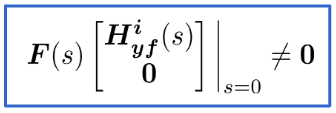

% only check those that are detectable
for i = 2:5
    disp(i)
    disp(simplify(limit(F * [Hyf(:,i); 0; 0],s, 0)))
end

     2



$$\left(\begin{array}{c} 0\\ -1 \end{array}\right)$$

     3



$$\left(\begin{array}{c} 0\\ k_{1} \end{array}\right)$$

     4



$$\left(\begin{array}{c} -1\\ -k_{1} \end{array}\right)$$

     5



$$\left(\begin{array}{c} 1\\ 0 \end{array}\right)$$

Evaluating at s=0 we see that:

$f_{\textrm{u2}}$ is strongly detectable on r2

$f_{\textrm{y1}}$ is strongly detectable on r2

$f_{\textrm{y2}}$ is strongly detectable on r1

$f_{\textrm{y2}}$ is strongly detectable on r2

$f_{\textrm{y3}}$ is strongly detectable on r1

## Q4

If the coloumb friction was known, the rank of Hyd would be zero, meaning the fault on f1 would also be weakly detectable.

rank(Hyf(:,1))

ans = 1